clear all; clc
%Defining constants
Ea = 13.4E10; %elastic modulus ceramic
Em = 200E9; %[MPa]; %elastic modulus steel

rho_s = 7.8E3; %kg/m^3
rho_a = 7.7E3; %kg/m^3
U0 = 3.3E-6; %m
ha0 = 2E-3; %m
Fout = 1100; %Newton

x_max = 11E-6; %m

sigmamax =	720E6;

AminCompression = 1100/2/sigmamax 

AminCompression = 7.6389e-07

AminCompression*1E6

ans = 0.7639

## Determining actuator height

wa = 7E-3; %width actuator
ha = (x_max + U0)/(U0/ha0 - Fout/(Ea * wa^2))*1E3

ha = 9.6461


wa = 10E-3;
ha = (x_max + U0)/(U0/ha0 - Fout/(Ea * wa^2))*1E3

ha = 9.1204

%Variables
tp = 7E-3; %Thickness plate
ts = 3E-3; %thickness spring
margin = 1E-3; %space between spring and actuator

wa = 7E-3; %actuator width
ha = 10E-3; %actuator height
ca = wa^2 *Ea/ha; %stiffnes actuator
ma = wa^2 * ha * rho_a; %mass actuator
umax = U0*(ha/ha0-1);


hp0 = 4; %starting height plate
hp1 = 20;%final height plate
hpstep = .1;
hp = [hp0:hpstep:hp1]*1E-3

hp =     0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049    0.0050    0.0051    0.0052    0.0053    0.0054    0.0055    0.0056    0.0057    0.0058    0.0059    0.0060    0.0061    0.0062    0.0063    0.0064    0.0065    0.0066    0.0067    0.0068    0.0069    0.0070    0.0071    0.0072    0.0073    0.0074    0.0075    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0082    0.0083    0.0084    0.0085    0.0086    0.0087    0.0088    0.0089


L1 = length(hp);

ws0 = 4; %width springs
ws1 = 50;
wsstep = .1;
ws = [ws0:wsstep:ws1]*1E-3

ws =     0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049    0.0050    0.0051    0.0052    0.0053    0.0054    0.0055    0.0056    0.0057    0.0058    0.0059    0.0060    0.0061    0.0062    0.0063    0.0064    0.0065    0.0066    0.0067    0.0068    0.0069    0.0070    0.0071    0.0072    0.0073    0.0074    0.0075    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0082    0.0083    0.0084    0.0085    0.0086    0.0087    0.0088    0.0089


L2 = length(ws);

Cs = zeros(L1,L2); Cp = zeros(L1,L2); Csys = zeros(L1,L2); Ctot = zeros(L1,L2); Sout = zeros(L1,L2); mtot = zeros(L1,L2);specCtot = zeros(L1,L2); specCsys = zeros(L1,L2);
isValid = zeros(L1,L2); areaValid = zeros(L1,L2);
for i=1:L1 %itterable hp
    for j=1:L2 %itterable ws
        %Computing dimensions
        L = wa + 2 * ws(j) + 2*margin;
        Ip = hp(i)^3 * tp / 12;
        %stiffness
        Cs(i,j) = ws(j)*ts*Em/ha;
        Cp(i,j) = 48 * Em * Ip / L^3;
        
        Csys(i,j) = 2*(1/Cp(i,j)+1/Cs(i,j))^-1;
        Ctot(i,j) = (1/(2*Cp(i,j)) + 1/(ca+2*Cs(i,j)))^-1;
        
        
        %output stroke
        Sout(i,j) = (ca*umax + Fout)/(ca+Csys(i,j))*1E6;
        isValid(i,j) = Sout(i,j) >= 11;
        areaValid(i,j) = ws(j)*ts >= AminCompression;
        
        %mass
        ms = ws(j)*ha*ts*rho_s;
        mp = L*hp(i)*tp*rho_s;
        mtot(i,j) = 2*ms + 2*mp + ma;
        %specific stroke
        specCsys(i,j) = Csys(i,j)/mtot(i,j);
        specCtot(i,j) = Ctot(i,j)/mtot(i,j);
        
    end
end

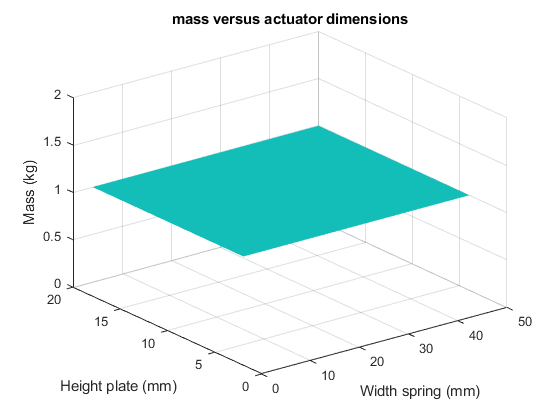




[X,Y] = meshgrid(ws0:wsstep:ws1,hp0:hpstep:hp1);
figure 
hold on
clf
s1 = surf(X,Y,areaValid);
s1.EdgeColor = 'none';

title('mass versus actuator dimensions')
xlabel('Width spring (mm)')
ylabel('Height plate (mm)')
zlabel('Mass (kg)')

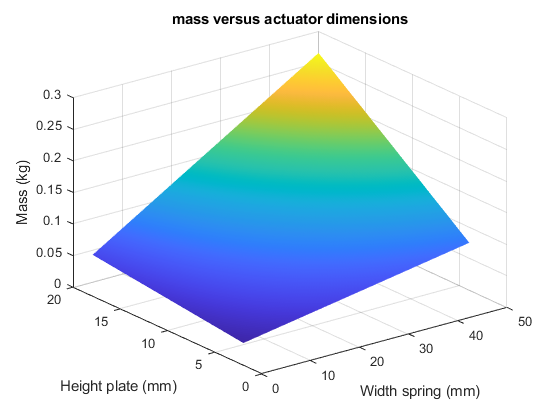



figure 
clf
s1 = surf(X,Y,mtot);
s1.EdgeColor = 'none';

title('mass versus actuator dimensions')
xlabel('Width spring (mm)')
ylabel('Height plate (mm)')
zlabel('Mass (kg)')

name = "ssa12/mass" + int2str(wa*1E3) +".png";
saveas(gcf,name)

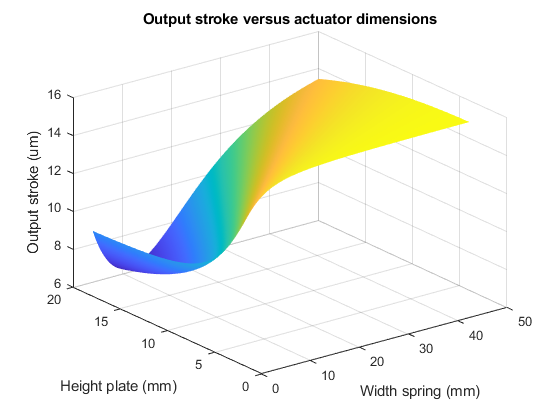


figure 
clf
s1 = surf(X,Y,Sout);
s1.EdgeColor = 'none';

title('Output stroke versus actuator dimensions')
xlabel('Width spring (mm)')
ylabel('Height plate (mm)')
zlabel('Output stroke (um)')

name = "ssa12/outputStroke" + int2str(wa*1E3) +".png";
saveas(gcf,name)

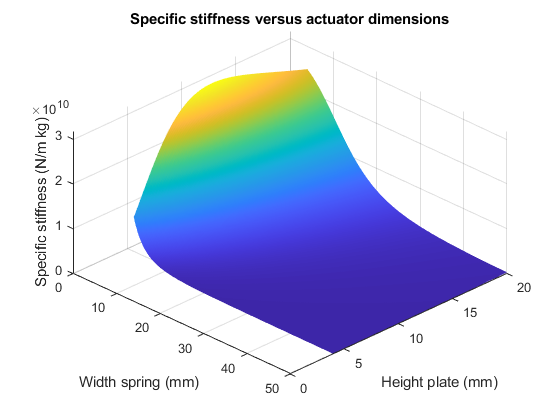

figure 
clf
s1 = surf(X,Y,specCtot);
s1.EdgeColor = 'none';

title('Specific stiffness versus actuator dimensions')
xlabel('Width spring (mm)')
ylabel('Height plate (mm)')
zlabel('Specific stiffness (N/m kg)')
view([45 45])
name = "ssa12/Ctot" + int2str(wa*1E3) +".png";
saveas(gcf,name)

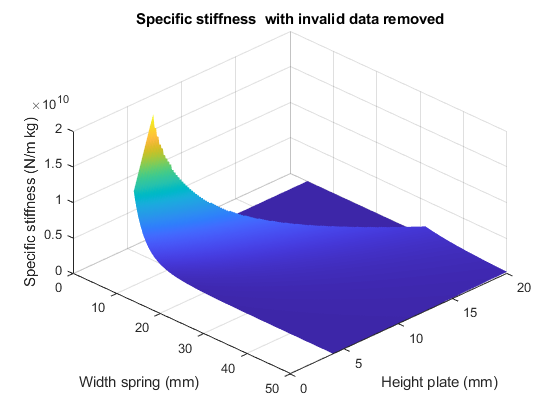



figure 
clf
s1 = surf(X,Y,specCtot.*isValid);
s1.EdgeColor = 'none';

title('Specific stiffness  with invalid data removed')
xlabel('Width spring (mm)')
ylabel('Height plate (mm)')
zlabel('Specific stiffness (N/m kg)')
view([45 45])
name = "ssa12/validCtot" + int2str(wa*1E3) +".png";
saveas(gcf,name)

validc= Ctot.*isValid;
max(max(validc))

ans = 3.1969e+08